data1 = readtable('Al-1Mg.xlsx');
data1.Properties.VariableNames = {'Strain','Strain Rate','T1','T2','T3','T4','T5','T6'}

data1 = 31×8 table
    Strain    Strain Rate     T1       T2       T3       T4      T5      T6 
    ______    ___________    _____    _____    _____    ____    ____    ____

     NaN           NaN         300      350      400     450     500     550
     0.1         0.001        75.3       44       24    13.9     8.6       5
     0.1          0.01        87.1       55       44    29.5    18.6    11.7
     0.1           0.1        99.6     91.2     73.9    54.8      36    22.7
     0.1             1       115.3    110.9     95.4    58.7    53.4      43
     0.1            10       130.2    119.6    105.8    70.5    68.6    51.2
     0.1           100       138.1    122.7      118    93.8    84.3    57.5
     0.2       

data1(1,:)=[];

C = {'m','b','r','g','y',[.8 .5 .9]};
modified_table= movevars(sortrows(data1,'Strain Rate'),'Strain Rate','Before','Strain');
stressvstrain = table2array(modified_table);
%by default strain rate = 1e-0.3
stress_at_dsr = [0,0,0,0,0,0;stressvstrain(1:5,3:end)];

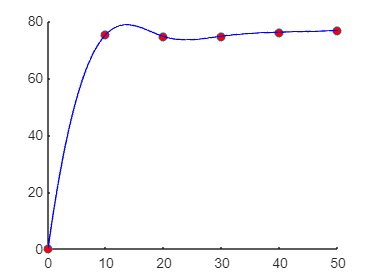

x = [0;stressvstrain(1:5,2)];
y = stress_at_dsr(:,1);
xx = 0:0.00001:0.5;
yy = spline(x,y,xx);
scatter(x*100,y,'Marker','o','MarkerFaceColor','r')
hold on
plot(xx*100,yy,'Color','b','LineWidth',1)

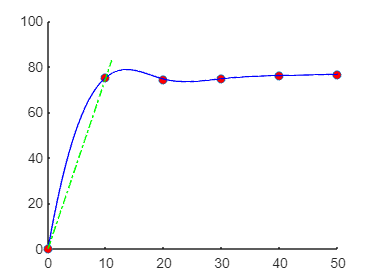

m = (y(2)-y(1))/ (x(2)-x(1));
x1 = 0:0.00001:0.11;
y1 = m*x1 + 0.02;
plot(x1*100,y1,'LineStyle','-.','Color','g');